Part I: Steady Flow in a Converging Blood Vessel

figure()
L = 10; %cm
R_0 = 1.5; %cm
StudentID = [56, 12, 17]; %last two digits of group's student ID numbers
U_0 = mean(StudentID); %cm
 
%equations that model the flow in the converging section
 
%{
from the assumption that the flow is steady, the derivatives of the 
equations that define the flow with respect to time ('du/dt'and 'dv/dt') 
must have a sum of zero. 
from this, the constants 'a' and 'b' were calculated to have 
the ratio of 1:2.8333. So, when 'a' obtains the value of 10, 
'b' correspondingly receives the value of 28.333.
%}
a = 10; 
b = 28.3333;
 
%{
create the meshgrid of cylindrical coordinates.
the coordinates are taken to match the given dimensions of the 
blood vessel geometry (10cm in length and 1.5 cm radii)
 
the 'x' values are said to corresponding to the values of length while the 
'y' values correspond to the varying radii lengths (distance from the 
middle of the cross-sectional area of the converging cylinder)
%}
 
[x,y] = meshgrid(0:0.5:10,-1.5:.15:1.5);
u = U_0*(((a.*x)/L)+1); 
v = -b.*y;
 
%create the 2D vector plot of the flow field
quiver(x,y,u,v);
daspect([1 1 1]);
 
%because we will superimpose streamlines/ if not here quiver plot is lost
hold on        
xlabel('x (cm)');
ylabel('y (cm)');
%axes are consistent with the measurements of the system
axis([0 10 -1.5 1.5]);
 
%Plot 20 streamlines for the flow fluid
x1 = linspace(0,10,20);
y1 = linspace(-1.5,-1.5,20);
 
x2 = linspace(0,10,20);
y2 = linspace(1.5,1.5,20);
 
streamline(x,y,u,v,x1,y1);
streamline(x,y,u,v,x2,y2);

Part II : Steady Flow of Opposite Impinging Streams

clear all;
clc;
%%finding the location of the stagnant point in flow field%%
% stagnant point is when velocity equals zero V= u+v where 
% u and v equal zero
syms x y % creates variables x and y 
u=0; % defines the value of u as zero 
v=0; % defines value of v as zero 
% u and v = 0 due to lagrangian equation for velocity: V = ui+vj=0 
u= 0.5 + 0.8*x; % defines equation for u and x
v = 1.5 - 0.8*y; % defines equation for v and y 
% find the values for x and y 
X=solve(u,x); % solves equation u for variable x in fraction form
Y=solve(v,y); % solves equation v for variable y in fraction form
% displays solution as a string with values as decimals instead of fractions 
stangnant_point =sprintf('x= %.15gm and y=%.15gm',X, Y)

stangnant_point = 'x= -0.625m and y=1.875m'

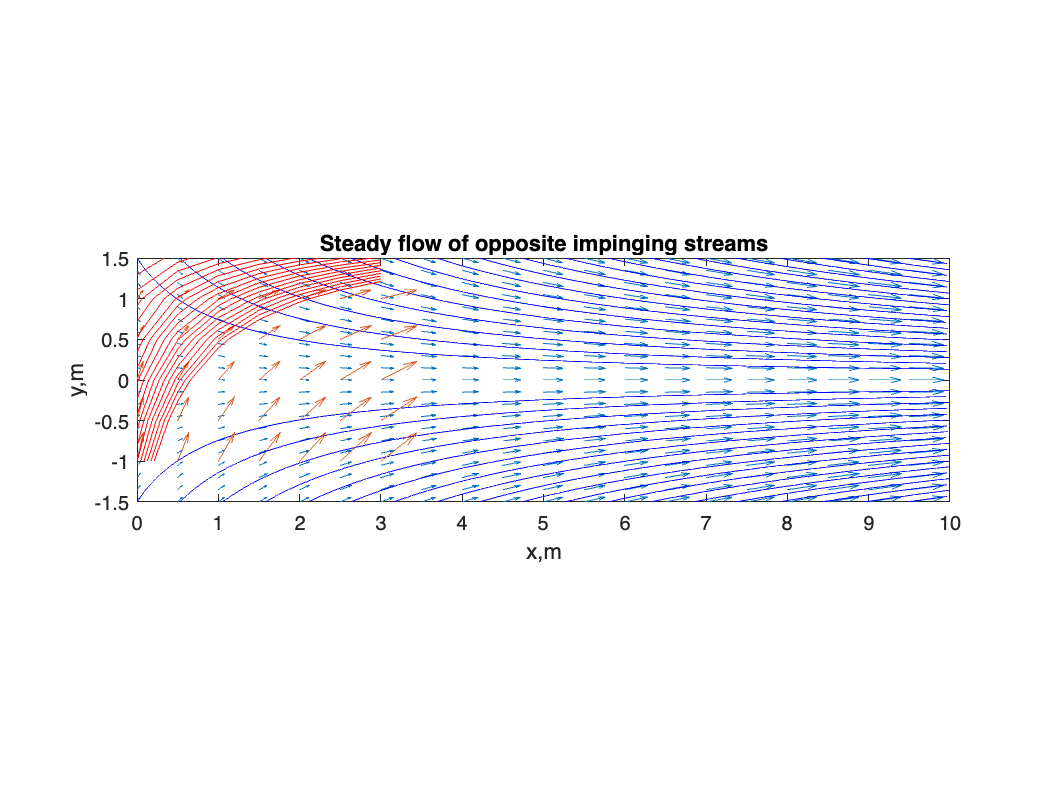


clc;
%% Create a 2D vector plot%%
% create meshgrid for x and y by defining the values 
%for x and y, fluid domain of interest, and select
% increments best suited for graph 
[x,y] = meshgrid(-3:.5:3,-1:.5:5); %m 
% defining the equations of the model of flow of the two fluid 
u= 0.5 + 0.8*x;
v = 1.5 - 0.8*y;
%to plot vectors use the command quiver and hold on to allow for input of
%stream lines to same graph
hold on;
quiver(x,y,u,v);
%since the flow is steady the u,v not dependent on time streamlines and
%pathlines are the same 
% Define the level set function F (for streamlines)
  F = (1.5-0.8*y)*(0.5+0.8*x);
% Define the 20 levels required for the streamlines
 C = 0:1:20;
 % Plot the contours where F = C(1), F = C(2), ...
 contour(x,y,F,C, 'LineColor','r')
xlabel('x,m');
ylabel('y,m');
title('Steady flow of opposite impinging streams');
hold off;

Part III: Unsteady Flow of Opposite Impinging Streams

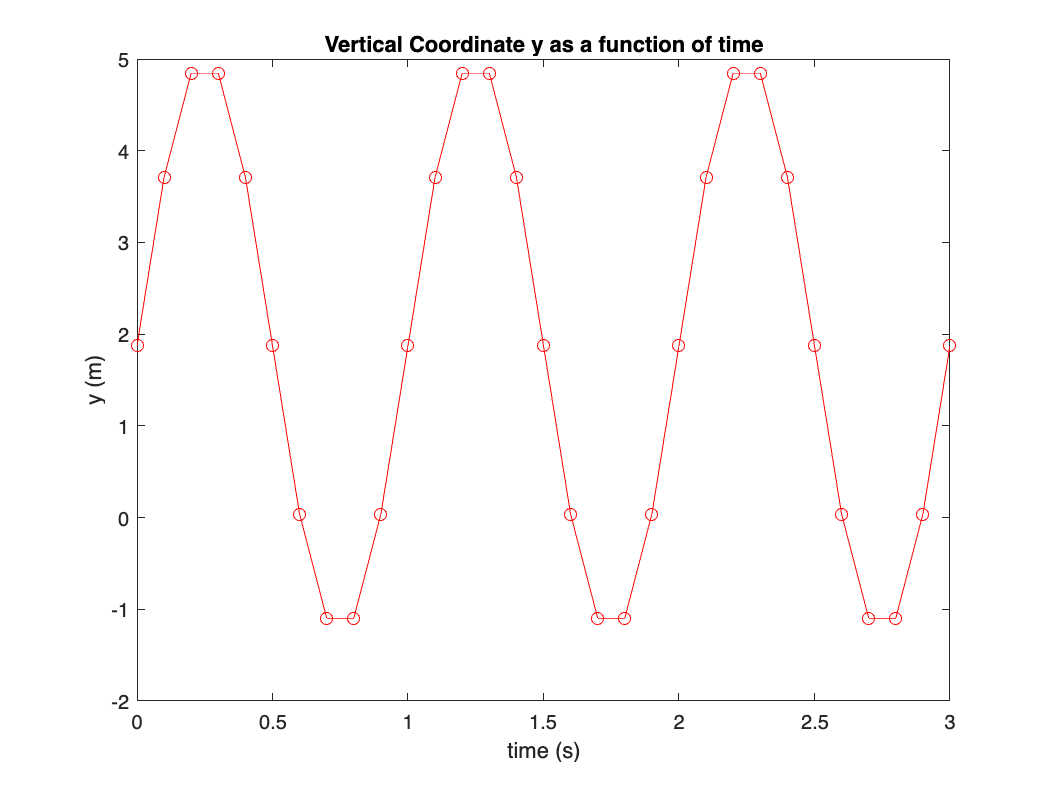

clc;
% Part 3 Unsteady Flow
 
 
%vertical coordinate y as a function of time
t=[0:.1:3]; %s
w=2*pi;
 
%expression for y(t)
y=(1.5+2.5*sin(t.*w))/0.8;   
plot(t,y,'ro-')
title("Vertical Coordinate y as a function of time")
xlabel('time (s)');
ylabel('y (m)');

Current plot released
Current plot released
Current plot released
Current plot released


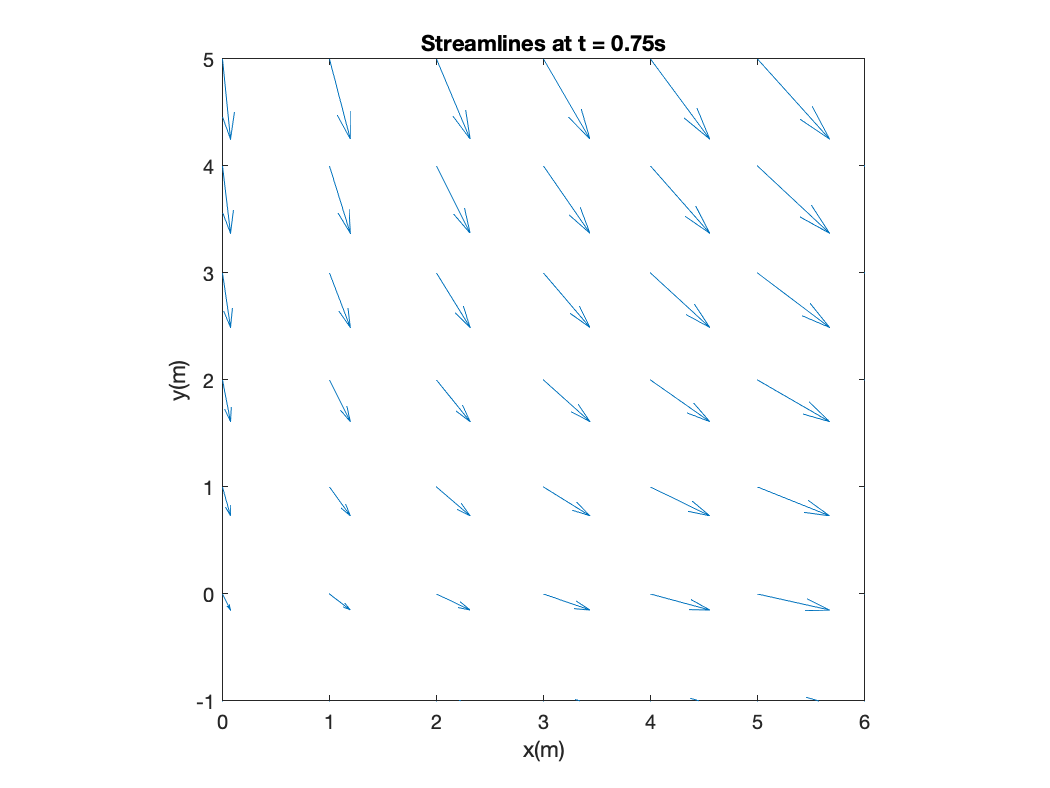

 
 
 
%Streamline superimposed onto vector plot
%meshgrid with Cartesian coordinates
[xv,yv]= meshgrid(0:1:6, -1:1:5);
vs=VideoWriter('streamlines.avi');      %creates file to store video
vs.FrameRate= (5);                      %sets frame rate to 5 frames per second
open(vs);                               %opens file
 
%time-dependant vector plot of velocity field
for t= 0:0.25:0.75 %s
    u= 0.5 + xv.*0.8;
    v= 1.5 + 2.5*sin(t.*w) - yv.*0.8;
    quiver(xv,yv,u,v);
    daspect([1,1,1]);
    hold on
    F= (v.*u);      %levelset function for streamlines
    C=0:1:19;       %creates 20 streamlines
    contour(xv,yv,F,C,'LineColor','b')    %superimposes streamlines onto vector field
    axis([0 6 -1 5])
    title("Streamlines at t = "+t+"s")
    xlabel('x(m)')
    ylabel('y(m)')
    drawnow
    hold 
    pause(0.5)
    writeVideo(vs,getframe(gcf));   %adds image to video 
end

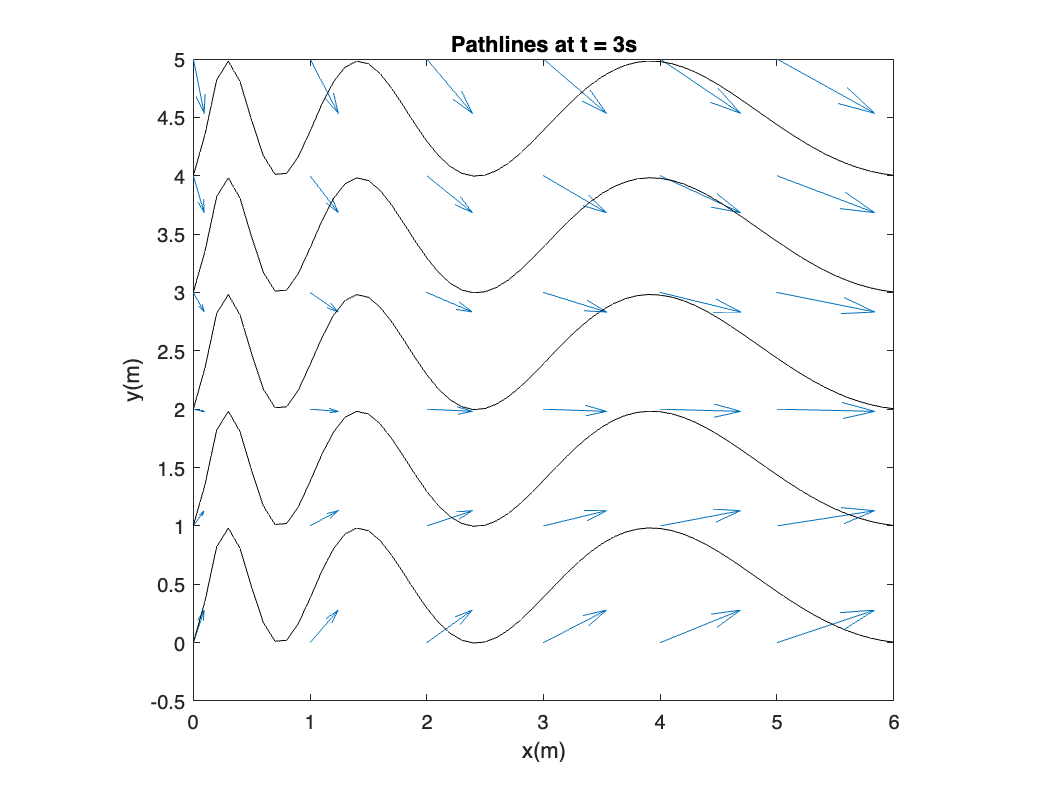

close(vs);      %closes file
clc;
 
 
%Pathlines superimposed onto vector field
%meshgrid with cartesian coordinates used for pathlines
[x,y]= meshgrid(0:.1:6, -1:.1:5);
%meshgrid with cartesian coordinates used for vector field
x0=0;t0=0;
vp=VideoWriter('pathlines.avi');       %creates file called pathlines
vp.FrameRate= (5);                      %sets frame rate to 5 frames/sec
open(vp);                               %opens file
%time-dependant vector plot of velocity field
for t=0:0.1:3
    u= 0.5 + xv.*0.8;
    v= 1.5 + 2.5*sin(t.*w) - yv.*0.8;
    quiver(xv,yv,u,v);    
    daspect([1,1,1]);
    for y0= 0:1:4
        hold on
       %particle tracking function:
        plot((0.625*(exp(0.8.*t))-0.625),(y0+(3.125/(0.64+w.^2))*((w+0.8*sin(w.*(t)))-(w.*cos(w.*(t))))), 'ok', 'markerface', 'm');
        
        %level set function
        F = (y0-y+(3.125/(0.64+w.^2))*((w+0.8*sin(w.*( 1.25*log(1.6*x+1))))-(w.*cos(w.*( 1.25*log(1.6.*x+1))))));
        contour(x,y,F,[0,0],'LineColor','k')    %superimposes pathlines onto vector field
        axis([0 6 -0.5 5])
        title("Pathlines at t = "+t+"s")
        xlabel('x(m)')
        ylabel('y(m)')
    hold off
    end
    drawnow
    writeVideo(vp,getframe(gcf));   %adds figure to file
end

close(vp);          %closes f